% experiment7.mlx
% ResNet50 WITHOUT Tranfer Learning

clc; clear; close all;
cd('~/Documents/jorgeMunoz/docMicrostructuresAI/experiments/conMatlab/experiment7/methods/')
gpu = gpuDevice

gpu =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3080'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 11.4000
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 10501423104 (10.50 GB)
           AvailableMemory: 9508290560 (9.51 GB)
       MultiprocessorCount: 68
              ClockRateKHz: 1800000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


%224x224 px
DatasetPath= '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

DatasetPath = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

[imdsTrain, imdsVal, imdsTest] = splitEachLabel(imds, 0.7, 0.2, 0.1,"randomized");
labelCount = countEachLabel(imdsTrain)

labelCount = 3×2 table
           Label           Count
    ___________________    _____

    annealing              4480 
    quenching              4480 
    quenching+tempering    4480 


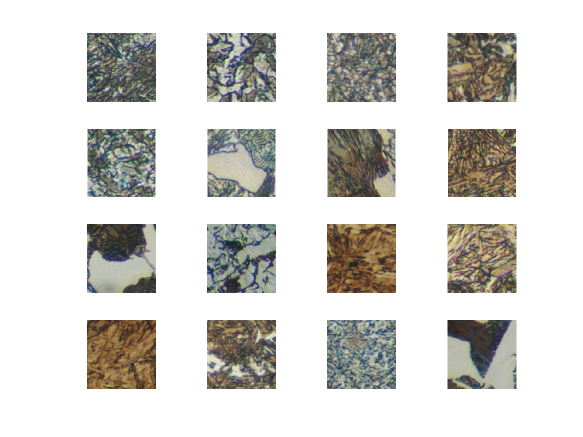

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end


net = resnet50('Weights','none');
 
%analyzeNetwork(net)



inputSize = net.Layers(1).InputSize

inputSize =    224   224     3



numClasses = numel(categories(imdsTrain.Labels))

numClasses = 3


newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name', 'Steel Feature Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

net = replaceLayer(net,'fc1000', newLearnableLayer);
%analyzeNetwork(net)



newClassLayer = classificationLayer('Name','new_classoutput')

net = replaceLayer(net, 'ClassificationLayer_fc1000', newClassLayer);


Minibatch_Size = 64;
validationFrequency = floor(numel(imdsTrain.Files)/Minibatch_Size);
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize', Minibatch_Size, ...
    'MaxEpochs', 3, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsVal, ...
    'ValidationFrequency', validationFrequency, ...
    'Verbose', false, ...
    'Plots', 'training-progress');


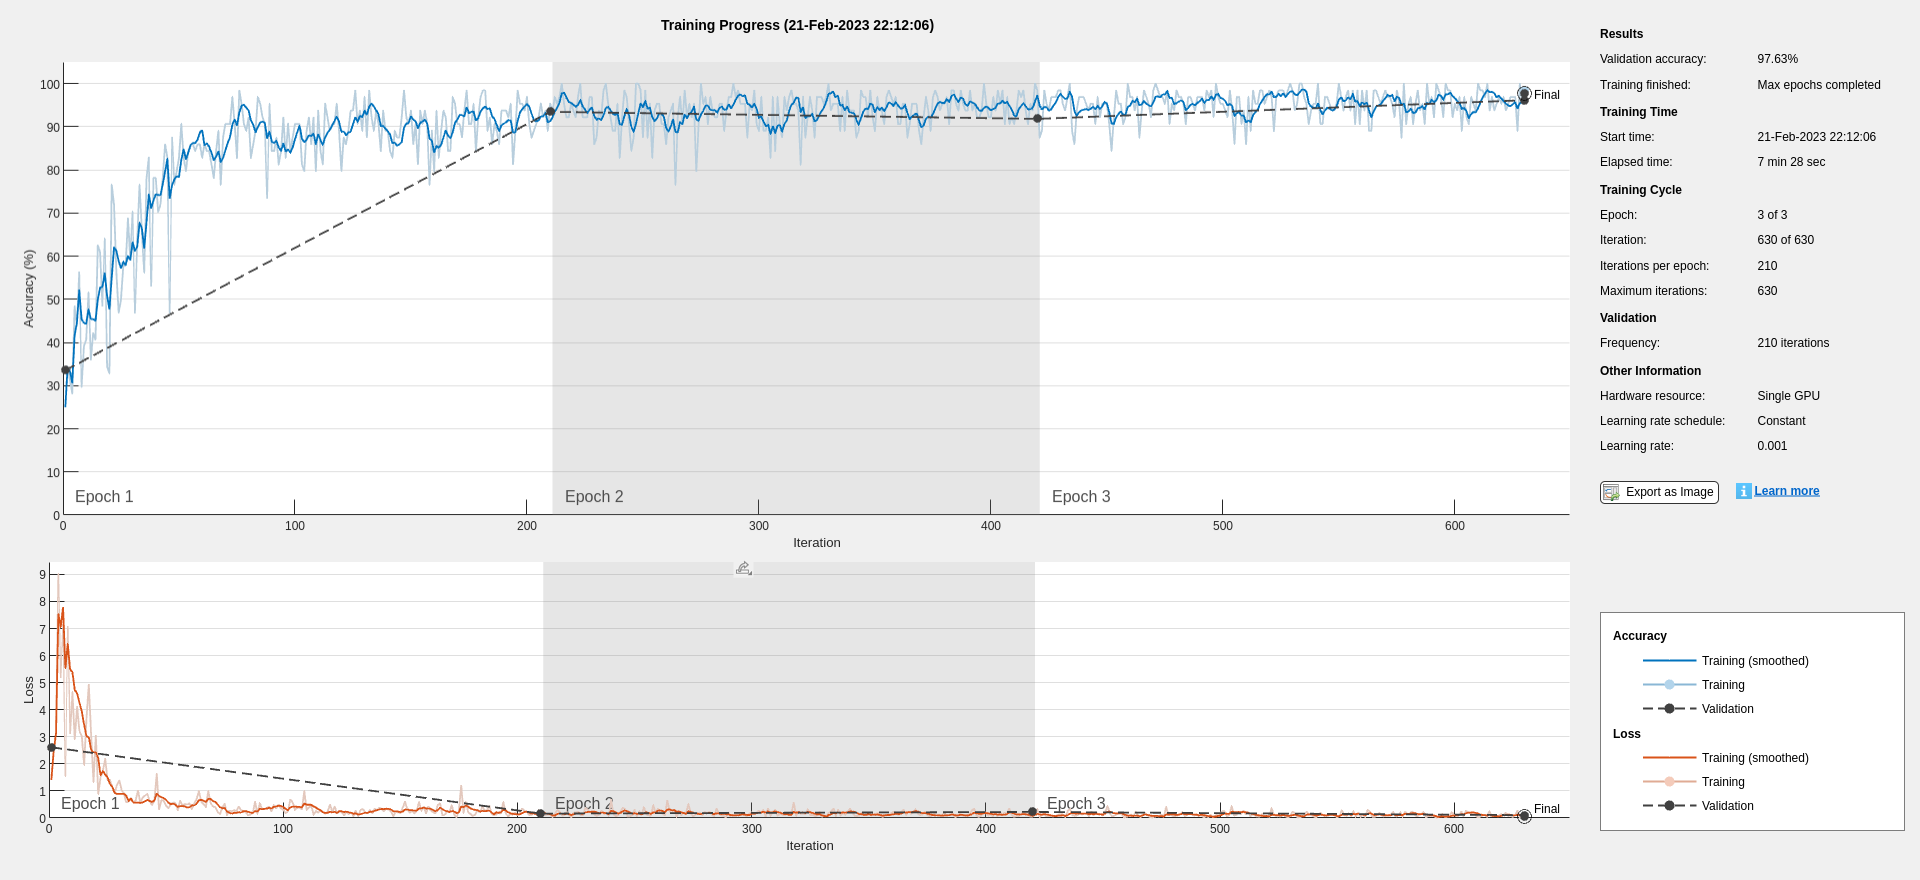


[net tr]= trainNetwork(imdsTrain, net, Training_Options);


% Accuracy (Val)
[YPred,probs] = classify(net,imdsVal);
accuracyVal = mean(YPred == imdsVal.Labels)

accuracyVal = 0.9766

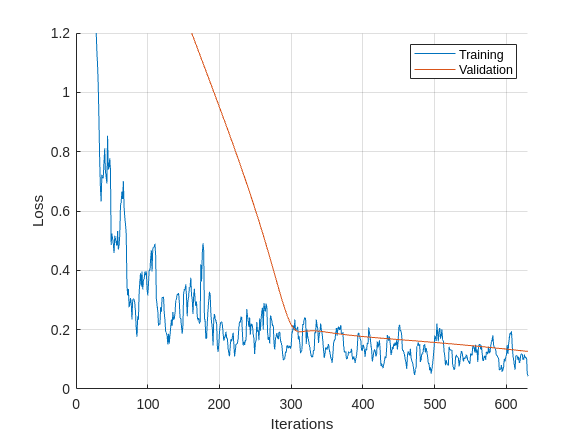

%Plot train 
%Loss
figure;
x = [1:630];
yl = tr.TrainingLoss;
yvl = tr.ValidationLoss;
plot(x, smooth(yl));
hold on;
plot(x, smooth(yvl));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [0 630 0 1.2] );
grid on;
xlabel('Iterations');
ylabel('Loss');

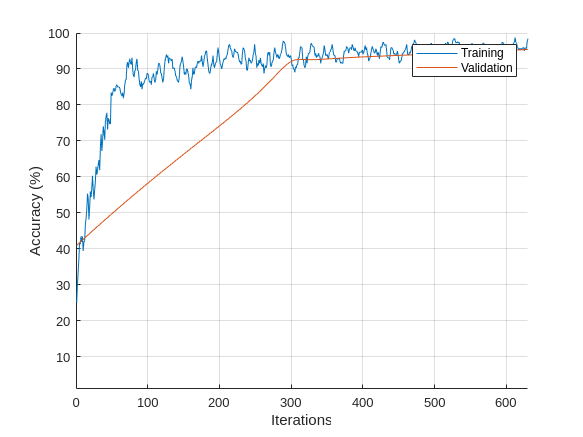


%Accuracy
figure;
x = [1:630];
y = tr.TrainingAccuracy;
yv = tr.ValidationAccuracy;
%yi = smooth(y);

plot(x, smooth(y));
hold on;
plot(x, smooth(yv));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [  0     630    1    100 ] );
grid on;
xlabel('Iterations');
ylabel('Accuracy (%)');

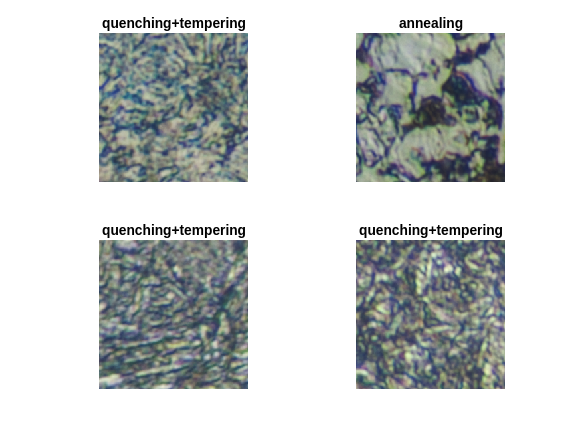


%TEST

[YPredTest,scores] = classify(net,imdsTest);
idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    %label = YPred(idx(i));
    label = YPredTest(idx(i));
    title(string(label));
end


YTest = imdsTest.Labels;
accuracyTest = mean(YPredTest == YTest)

accuracyTest = 0.9813

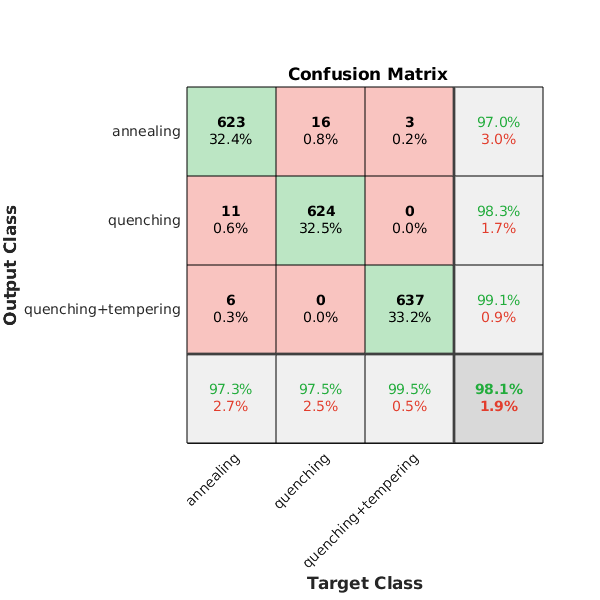

plotconfusion(YTest, YPredTest)

T = cMetrics(YTest, YPredTest)

Accuracy = 98.12%

T = 5×5 table
                           Precision    Recall      Fallout     Specificity      F1   
                           _________    _______    _________    ___________    _______

    annealing                0.9704     0.97344     0.014844      0.98516      0.97192
    quenching               0.98268       0.975    0.0085938      0.99141      0.97882
    quenching+tempering     0.99067     0.99531    0.0046875      0.99531      0.99299
    Avg                     0.98125     0.98125     0.009375      0.99062      0.98124
    WgtAvg                  0.98125     0.98125     0.009375      0.99062      0.98124


% For Matthew correlation coefficient
confM = confusionmat(YPredTest, YTest);
multiMetrics = multiclass_metrics_special(confM);

writetable(T,'metricasResNet50NTL.xls')

save('experiment7Workspace.mat')
